## **Speech Processing**

#### **Programming Assignmnet**

**Giving Input as Audio File and also Plotting it**

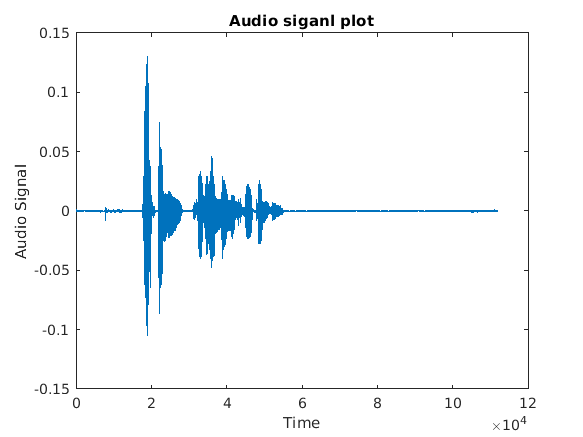


%short term fourier transform
[y,fs]=audioread('M017AA1S03.wav');
plot(y)
xlabel('Time')
title(" Audio siganl plot ")
ylabel('Audio Signal')

q = 1:1:length(y);

**Code for STFT**

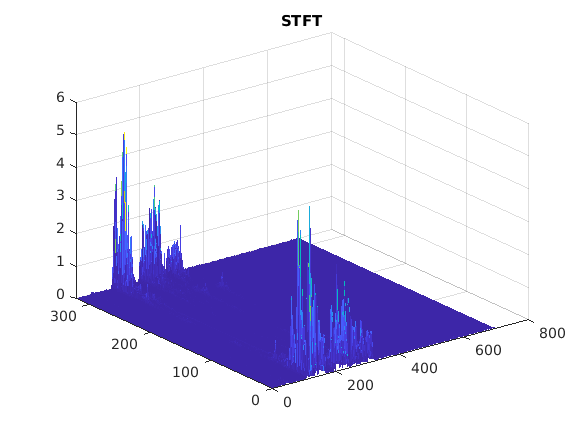


ktotal = 112000;
w = 1:1:ktotal;
j=1j;


FT = zeros(320,698);
z = zeros(1,ktotal);


c=0;

final = zeros(1,160);
for n=320:160:ktotal
    c=c+1;
 
    windy =y(160*(c-1)+1:160*(c+1));
     
        FT( :,c) = abs(fft(windy,320));
         SPEC(c,:) = log(abs(fft(windy,320)));
        
    end

surf(FT,'EdgeColor','none')
title('STFT')

**Code for True Spectrum & Convoluted spectrum**

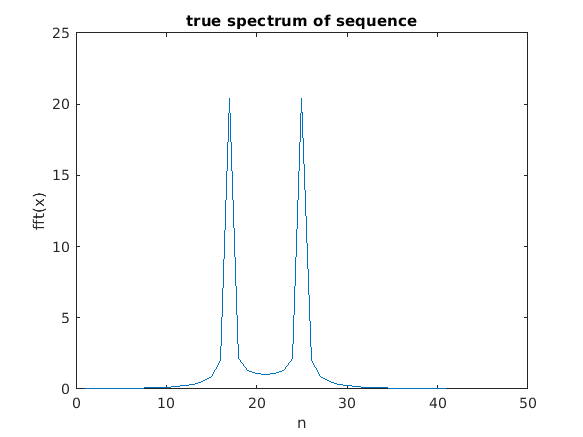

%true spectrum
 n=-2:.1:2;
 x=cos(2*pi*n);
 tr=fftshift(abs(fft(x)));
 length(tr);
 plot(tr)
 title(" true spectrum of sequence ")
 xlabel('n')
 ylabel('fft(x)')

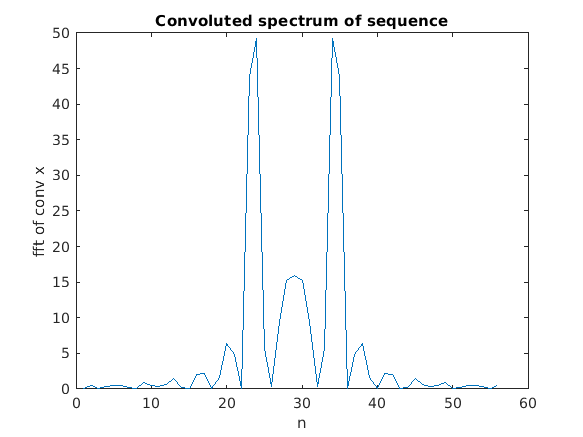

 
 %convoluted spectrum
 con = conv(x,rectwin(16));
 co = fftshift(abs(fft(con)));
 plot(co)
 title(" Convoluted spectrum of sequence ")
 xlabel('n')
 ylabel('fft of conv x')

%spectrogram
%spectrogram(y,hamming(256),128)

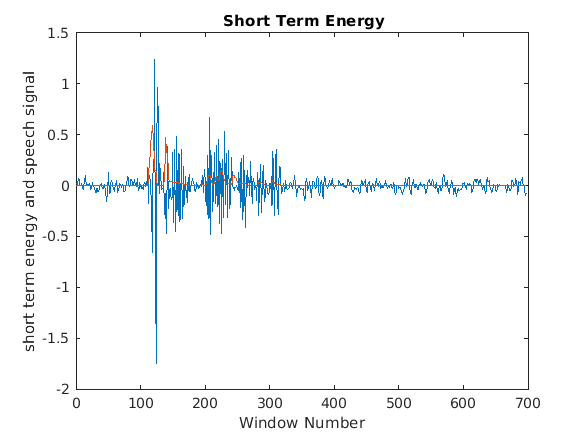

%short term energy and zero crossing 
zer=zeros(697,1);
energy = zeros(697,1);
yw = zeros(697,1);
for i=1:697%number of windows
    for j=1:320%window size
    yw(i) = yw(i) + y(160*(i-1)+j);
    energyw(j)=y(160*(i-1)+j)*y(160*(i-1)+j);
    if((sign(y(160*(i-1)+j)))*(sign(y(160*(i-1)+j+1)))==-1)
        zer(i)=zer(i)+1;
    end
    energy(i)= energy(i) + energyw(j);
    end
end
g=1:1:697;
plot(g,yw);
hold on;
plot(g,energy);
title(" Short Term Energy")
xlabel('Window Number')
ylabel('short term energy and speech signal')
hold off;

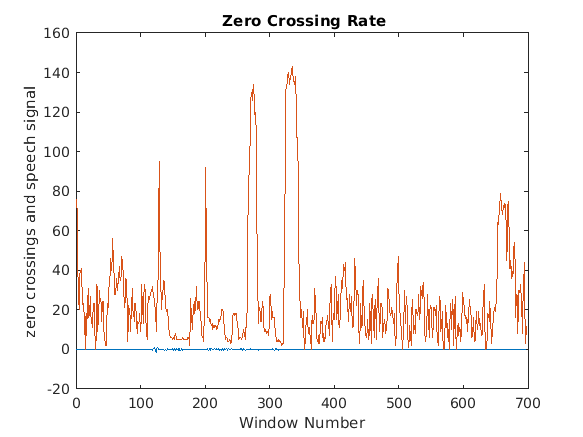

plot(g,yw);
 hold on;
plot(g,zer);
title(" Zero Crossing Rate")
    
xlabel('Window Number')
ylabel('zero crossings and speech signal')

**Short Term Plot Individually**

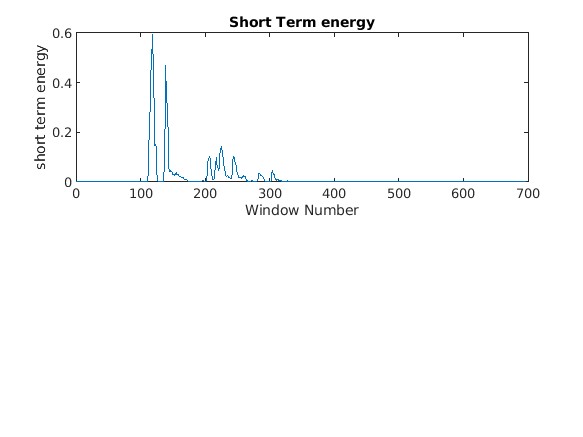


subplot(2,1,1)
    plot(g,energy)
    title('Short Term energy')
xlabel('Window Number')
ylabel('short term energy')

**Zero Crossing Plot Individually**

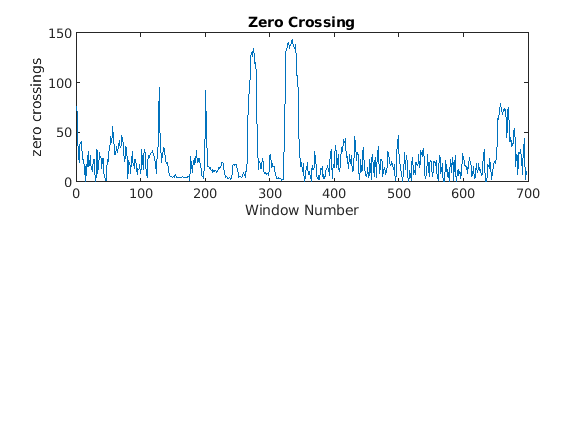


subplot(2,1,1)
    plot(g,zer)
    title('Zero Crossing')
xlabel('Window Number')
ylabel('zero crossings')